# First, make struct R for each Behavior session and save to folder

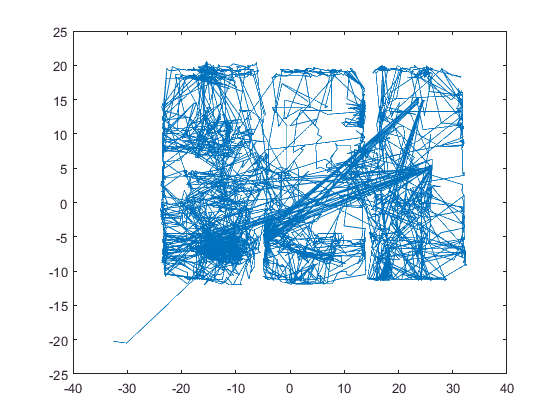

maxcells=13;
[R]=ExtractData_mac(0,maxcells);
save('R', 'R')
%sanity check

plot(R.Pos.x1,R.Pos.y1)

now you can run fullsplit for 

each cell, which saves struct Split, divided into sessions.

close all

numTetrodes=size(R.Spike.x);
for tetrode=1:numTetrodes(2)
    for unit=1:length(R.Spike.x)
        if isempty(R.Spike.x{unit,tetrode})
        else
        fullSplit(tetrode,unit,R.Pos.x1,R.Pos.y1,R.Pos.t,R.Spike.x(unit,tetrode),R.Spike.y(unit,tetrode),R.Spike.t(unit,tetrode),R.TimeStamps,R.mapAxis,R.p,R.visited)
        AllHeatMaps
        end
    end
end

Now you can look at behavior! First get time in each chamber for each session.

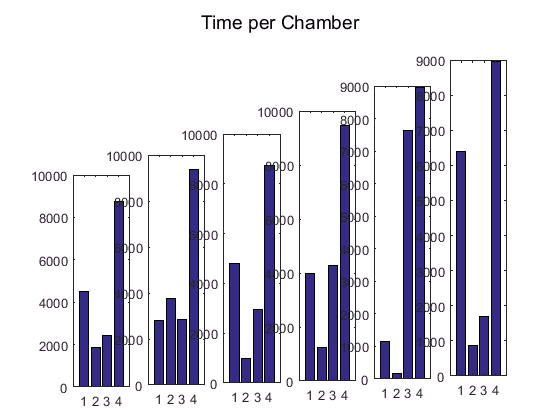

clearvars

list_cells=num2str(ls('TT*unit*'));
sessions={'hab', 'cups', 'fam1', 'nov', 'fam2','nov2'};


    for j=1:length(sessions)
        cd(list_cells(1,1:end))
        load('Split.mat')
        thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        posx=eval(strcat('Split.',thisSession,'.posx'));
        posy=eval(strcat('Split.',thisSession,'.posy'));
        post=eval(strcat('Split.',thisSession,'.post'));
        spkx=eval(strcat('Split.',thisSession,'.spkx'));
        spky=eval(strcat('Split.',thisSession,'.spky'));
        cd ..
        [~,~,time,~,~]=splitChambers(posx,posy,post,spkx,spky, thisSession);
        timeinchamber(j,1:4)=time;
  end
    figure()
    for j=1:length(sessions)
        subplot(1,length(sessions),j)
        bar(timeinchamber(j,:))
        suptitle('Time per Chamber')
    end

    
    save('timeinchamber','timeinchamber')
    


Now you can look at firing rate per chamber

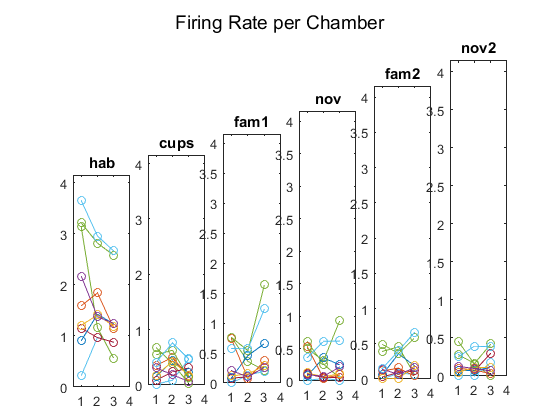

clearvars

list_cells=num2str(ls('TT*unit*'));
sessions={'hab', 'cups', 'fam1', 'nov', 'fam2','nov2'};
load('R.mat')
warning('off','all')
for i=1:length(list_cells)
    cd(list_cells(i,1:8))
    load Split.mat
    for j=1:length(sessions)
         thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        posx=eval(strcat('Split.',thisSession,'.posx'));
        posy=eval(strcat('Split.',thisSession,'.posy'));
        post=eval(strcat('Split.',thisSession,'.post'));
        spkx=eval(strcat('Split.',thisSession,'.spkx'));
        spky=eval(strcat('Split.',thisSession,'.spky'));
        [map,pospdf] = ratemap(spkx,spky,posx,posy,post,R.p.smoothing,R.mapAxis,R.mapAxis);
        div=length((R.mapAxis)+1)/3;
        leftmap=map(:,1:div); m1=nanmean(leftmap);avgFR_left=mean(m1);
        centermap=map(:,div:2*div);m2=nanmean(centermap);avgFR_center=mean(m2);
        rightmap=map(:,2*div:3*div);m3=nanmean(rightmap);avgFR_right=mean(m3);
        firingRate{i,j}=[avgFR_left avgFR_center avgFR_right];

    end
    cd ..
end

save('firingRate','firingRate')

for j=1:length(sessions)
    subplot(1,length(sessions),j)
    for i=1:length(list_cells)
        plot(firingRate{i,j},'-o')
        hold on
    end
    axis([0.5 4 0 max(max(cell2mat(firingRate)))+.5])
    title(sessions(j))
    suptitle('Firing Rate per Chamber')
    hold off
end

plot average firing rate per chamber

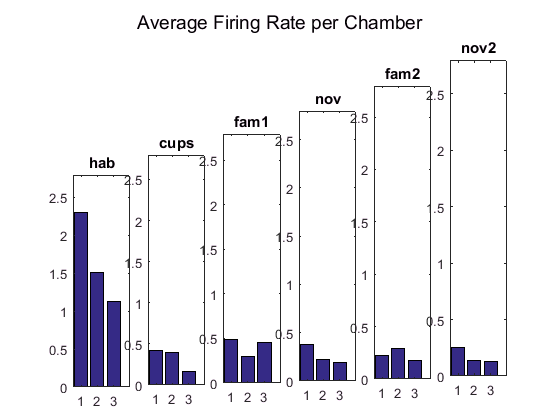

figure()
meanFR=cell(1,length(sessions));
for j=1:length(sessions)
    leftmean=ones(length(firingRate),1);
    centermean=ones(length(firingRate),1);
    rightmean=ones(length(firingRate),1);
    for i=1:length(list_cells)
          leftmean(i)=firingRate{i,j}(1,1);
          centermean(i)=firingRate{i,j}(1,2);
          rightmean(i)=firingRate{i,j}(1,end);
    end
    leftmean=mean(leftmean);
    centermean=mean(centermean);
    rightmean=mean(rightmean);
    meanFR{1,j}=[leftmean centermean rightmean];
    subplot(1,length(sessions),j)
    bar(meanFR{1,j})
    axis([0.5 4 0 max(cell2mat(meanFR))+.5])
    title(sessions(j))
    suptitle('Average Firing Rate per Chamber')
end

now break it down into interaction zones.  first find the cup centers

clearvars; load('R.mat')
figure()
[cups.lxc,cups.lyc]=findcup(R.Pos.x1,R.Pos.y1)
[cups.rxc,cups.ryc]=findcup(R.Pos.x1,R.Pos.y1)

save('cups','cups')

then set up your interaction zone

list_cells=num2str(ls('TT*unit*'));
sessions={'hab', 'cups', 'fam1', 'nov', 'fam2','nov2'};
for i= 1:length(list_cells)    
    thisCell=list_cells(i,1:9);
    cd(thisCell);
    load('Split.mat')
    for j=1:length(sessions)
        thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        posx=eval(strcat('Split.',thisSession,'.posx'));
        posy=eval(strcat('Split.',thisSession,'.posy'));
        post=eval(strcat('Split.',thisSession,'.post'));
        spkx=eval(strcat('Split.',thisSession,'.spkx'));
        spky=eval(strcat('Split.',thisSession,'.spky'));
        ts=eval(strcat('Split.',thisSession,'.spkt'));
        [leftCup, rightCup]=findIntTimes(cups.lxc,cups.lyc,cups.rxc,cups.ryc,posx,posy,post,spkx,spky,ts);
        cd(thisSession)
        save('leftCup','leftCup');save('rightCup','rightCup')
        cd ..
    end
cd ..
end

clear 
close all

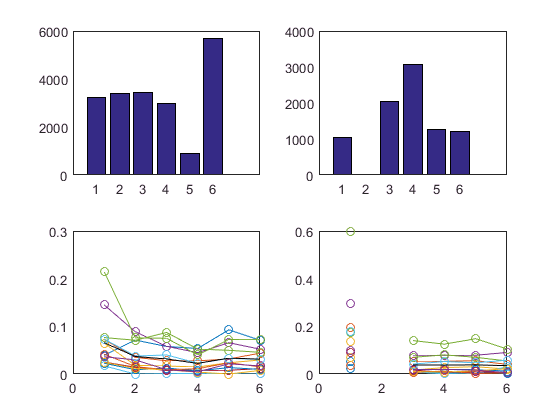

list_cells=num2str(ls('TT*unit*'));
sessions={'hab', 'cups', 'fam1', 'nov', 'fam2','nov2'};
for i= 1:length(list_cells)    
    thisCell=list_cells(i,1:9);
    cd(thisCell)
    for j=1:length(sessions)
        thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat')
        timeinLIntZone(i,j)=length(leftCup{5});
        spikesinLIntZone(i,j)=leftCup{7};
        load('rightCup.mat')
        timeinRIntZone(i,j)=length(rightCup{5});
        spikesinRIntZone(i,j)=rightCup{7};
        cd ..
    end
    cd ..
end

subplot(2,2,1)
bar(timeinLIntZone(1,1:6))
subplot(2,2,2)
bar(timeinRIntZone(1,1:6))
subplot(2,2,3)
plot((spikesinLIntZone./timeinLIntZone)','-o'); hold on; plot(mean(spikesinLIntZone./timeinLIntZone)','k');hold off
subplot(2,2,4)
plot((spikesinRIntZone./timeinRIntZone)','-o');hold on; plot(mean(spikesinRIntZone./timeinRIntZone)','k');hold off


save('timeinLIntZone','timeinLIntZone');save('spikesinLIntZone','spikesinLIntZone');
save('timeinRIntZone','timeinRIntZone');save('spikesinRIntZone','spikesinRIntZone');


now make rasters for interaction time; first find different bouts of interaction and then plot rasters

clearvars
list_cells=num2str(ls('TT*unit*'));
sessions={'cups', 'fam1', 'nov', 'fam2'};
for i= 1:length(list_cells)    
    thisCell=list_cells(i,1:9);
    cd(thisCell)
    for j=1:length(sessions)
        thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat')
        post=leftCup{4};
        ts=leftCup{3};
        %find individual trials by finding breaks in post
        diffPost=diff(post); breakInds=diffPost>(mode(diffPost)+0.01);%add a little buffer to this since timestamps aren't perfect
        trials=(find(breakInds==1));trialInds=find(diff(trials)>4);trials=trials(trialInds);
        %trial starts are the odds in trialStarts, trial ends are the evens
        trialStart=trials(1:2:length(trials));trialEnd=trials(2:2:length(trials));
        numTrials=length(trialEnd);
        for tr=1:numTrials
            Start=trialStart(tr);End=trialEnd(tr);
            thisTrial_post{tr}=post(Start:End);
            thisTrial_spk_ind=find(ts>post(Start)&ts<post(End));
            thisTrial_spk{tr}=ts(thisTrial_spk_ind);
        end
        
       % note this could be zero if you wished
        markerSize = 12;
        
       
        figure(i)
        for tr = 1:numTrials
            spikesT = thisTrial_spk{tr}-thisTrial_post{tr}(1,1);
            TrialS=thisTrial_post{tr}(1,1);
            TrialLength=(thisTrial_post{tr}(end,1)-TrialS);
            convFact=1/TrialLength;
            trialMarks=[0 TrialLength];
            spikesT_norm= convFact*spikesT;
            yVals = tr + 0*spikesT;  % offset by one vertically for each trial
            subplot(1,length(sessions),j)
            plot(spikesT_norm, yVals, 'r.', 'markerSize', markerSize);
            hold on
            axis([-.25 1.25 0 length(trialStart)])
            title(thisSession)
            
        end

        
        cd ..
    end
    fig=figure(i);
    save('normRasters','fig')
    close all
    cd ..
end

clearvars
list_cells=num2str(ls('TT*unit*'));
sessions={'cups', 'fam1', 'nov', 'fam2'};
for i= 1:length(list_cells)    
    thisCell=list_cells(i,1:9);
    cd(thisCell)
    for j=1:length(sessions)
        thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        cd(thisSession)
        load('leftCup.mat')
        post=leftCup{4};
        ts=leftCup{3};
        %find individual trials by finding breaks in post
        diffPost=diff(post); breakInds=diffPost>(mode(diffPost)+0.01);%add a little buffer to this since timestamps aren't perfect
        trials=(find(breakInds==1));trialInds=find(diff(trials)>4);trials=trials(trialInds);
        %trial starts are the odds in trialStarts, trial ends are the evens
        trialStart=trials(1:2:length(trials));trialEnd=trials(2:2:length(trials));
        numTrials=length(trialEnd);
        for tr=1:numTrials
            Start=trialStart(tr);End=trialEnd(tr);
            thisTrial_post{tr}=post(Start:End);
            thisTrial_spk_ind=find(ts>post(Start)&ts<post(End));
            thisTrial_spk{tr}=ts(thisTrial_spk_ind);
        end
        
       % note this could be zero if you wished
        markerSize = 12;
        
       
        figure(i)
        for tr = 1:numTrials
            spikesT = thisTrial_spk{tr}-thisTrial_post{tr}(1,1);
            TrialS=thisTrial_post{tr}(1,1);
            TrialLength=(thisTrial_post{tr}(end,1)-TrialS);
            convFact=1/TrialLength;
            trialMarks=[0 TrialLength];
            spikesT_norm= convFact*spikesT;
            yVals = tr + 0*spikesT;  % offset by one vertically for each trial
            subplot(1,length(sessions),j)
            plot(spikesT_norm, yVals, 'r.', 'markerSize', markerSize);
            hold on
            axis([-.25 1.25 0 length(trialStart)])
            title(thisSession)
            
        end

        
        cd ..
    end
    fig=figure(i);
    save('normRasters','fig')
    close all
    cd ..
end

Now look at correlations between sessions

tic
clearvars
list_cells=num2str(ls('TT*unit*'));

sessions={'hab', 'cups', 'fam1', 'nov', 'fam2','nov2'};
load('R.mat')

pop_mat=cell(1,length(sessions));
for j=1:length(sessions)
    thisSession=sessions(j);
    thisSession=cellstr(thisSession);
    thisSession=char(thisSession);
    allmaps=cell(length(list_cells),1);
    
    
    for i=1:length(list_cells)
       thisCell=list_cells(i,1:9);
       cd(thisCell)
       load('Split.mat')
       map=splitMaps(Split,R,1);
       thisMap=eval(strcat('map.',thisSession));
       allmaps{i}=thisMap;
       cd ..
       
    end
    pop_mat{1,j}=allmaps;
end
toc

pop_corr=zeros(length(list_cells),(length(sessions)-1));
p_vals=zeros(length(list_cells),(length(sessions)-1));

    for ii=1:length(list_cells)
    for jj=1:length(sessions)-1
        sess1=pop_mat{1,jj}{ii,1}(R.visited==1);
        sess2=pop_mat{1,jj+1}{ii,1}(R.visited==1);
        [r,p]=corrcoef(sess1,sess2);
        pop_corr(ii,jj)=r(2,1);
        p_vals(1,jj)=p(2,1);
    end
    end
    
    

for i=1:length(list_cells)
    plot(pop_corr(i,:))
    hold on
    axis([.5 4.5 -.5 1])
end
plot(mean(pop_corr),'k','linewidth',4) 
title('Spatial Corr by cell')



for i=1:length(list_cells)
    for j=1:length(sessions)
        Size=size(map.hab);
        pop_vect{i,j}=reshape(pop_mat{1,j}{i,1},[1,Size(1)* Size(2)]);
        
    end
end
for i=1:length(list_cells)
    for j=1:length(sessions)
        Size=size(map.hab);
        pop_vect(1,j)=vertcat(cell2mat(pop_vect{i,j}))
        
    end
end

%dist from cup analysis
list_cells=num2str(ls('TT*unit*'));
sessions={'hab', 'cups', 'fam1', 'nov', 'fam2'};
for i= 1:length(list_cells)    
    thisCell=list_cells(i,1:8);
    cd(thisCell);
    load('Split.mat')
    for j=1:length(sessions)
        thisSession=sessions(j);
        thisSession=cellstr(thisSession);
        thisSession=char(thisSession);
        posx=eval(strcat('Split.',thisSession,'.posx'));
        posy=eval(strcat('Split.',thisSession,'.posy'));
        spkx=eval(strcat('Split.',thisSession,'.spkx'));
        spky=eval(strcat('Split.',thisSession,'.spky'));
        [dist_cup{i,j},avgDist{i,j}]=dist_fromCup(posx,posy,spkx,spky,cups.lxc,cups.lyc);
       
    end
    cd ..
end

plot velocity over time in 1 sec bins

    clearvars; load('R.mat')
    vel=velocityLinear(R.Pos.x1,R.Pos.t);
    plot(vel,R.Pos.t)